Ft=tf([1],[1 2 3])

Ft =
 
        1
  -------------
  s^2 + 2 s + 3
 
Continuous-time transfer function.




input=1;
samplingtime=0;
zeta=0.7

zeta = 0.7000

ts=1.5

ts = 1.5000

DESIGN_CRITERIA = containers.Map({'zeta', 'ts'}, {zeta, ts});

ControladorPID=PIDController(input,DESIGN_CRITERIA,samplingtime);
ControladorPID.setTransferfunction(Ft);
ControladorPID.getTransferfunction()

ans =
 
        1
  -------------
  s^2 + 2 s + 3
 
Continuous-time transfer function.



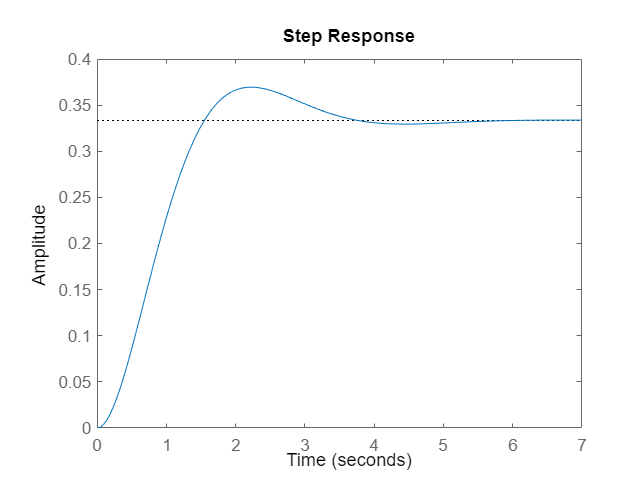

ControladorPID.initializeWithTf();
ControladorPID.startComputesPID();
% step(ControladorPID.getTransferfunction())

ControladorPID

ControladorPID =   PIDController with properties:

                      numPID: []
                      denPID: []
                   PIDValues: [1×1 struct]
                     PIDType: []
         PIDTransferFunction: (kd1*s^2 + kp*s + ki1)/s
            numOfIntegrators: 1
                       input: 1
             design_criteria: [2×1 containers.Map]
            transferFunction: [1×1 tf]
                samplingTime: 0
              controlability: 1
               observability: -1
                           A: [2×2 double]
                           B: [2×1 double]
                           C: [0 1]
                           D: 0
                           E: []
                           F: []
                           S: [2×2 double]
                           O: [2×2 double]
                         num: [0 0 1]
                         den: [1 2 3]
                  plantRoots: [2×1 double]
      

structType=ControladorPID.PIDValues

structType = struct with fields:
    kd1: 16.6667
    ki1: 193.4996
     kp: 82.6236


fieldnames(structType)

ans = 3×1 cell array
    {'kd1'}
    {'ki1'}
    {'kp' }


% kd1=getfield(structType,"kd1",'kp')


ControladorServo=ServoController(0,DESIGN_CRITERIA,0);
ControladorServo.setTransferfunction(Ft);
ControladorServo.initializeWithTf();
ControladorServo.defineDesirePolinomialSize();
ControladorServo.getDesirePolinomial();
ControladorServo

ControladorServo =   ServoController with properties:

                           K: []
                     K_acker: []
                       input: 0
             design_criteria: [2×1 containers.Map]
            transferFunction: [1×1 tf]
                samplingTime: 0
              controlability: 1
               observability: -1
                           A: [2×2 double]
                           B: [2×1 double]
                           C: [0 1]
                           D: 0
                           E: []
                           F: []
                           S: [2×2 double]
                           O: [2×2 double]
                         num: [0 0 1]
                         den: [1 2 3]
                  plantRoots: [2×1 double]
                  plantPoles: [0×1 double]
                          Mp: []
                        zeta: 0.7000
                          Wn: 3.8095
             

ControladorServo.A

ans =     -2    -3
     1     0



ControladorServo.getKforAckerMethod();
ControladorServo.K_acker

ans =    16.6667   82.6236


roots(ControladorServo.desirePolinomial)

ans =  -13.3333 + 0.0000i
  -2.6667 + 2.7205i
  -2.6667 - 2.7205i


% K=acker(ControladorServo.A,ControladorServo.B,roots(ControladorServo.desirePolinomial))

Error using acker (line 37)
Vector P must have SIZE(A) elements